clear all;
clc;

## Regression CNN model for PM2.5

% Data preparation
myFolder = '/Users/lincolntoo/Desktop/Capstone 180/figuredata';
% PM2.5 measurements 
PMtbl = readtable('/Users/lincolntoo/Desktop/Capstone 180/figuredata/PMdata.csv');
fileName_array = PMtbl.('fileName');
PM25_array = PMtbl.("PM25");

% M x N is the image size
M = 224; %960;
N = 224; %1280;

imageSize = [M N 3];

% First, load the images into 4D arrays
imageArray = zeros(M,N,3,206); % Where N and M are your image size

% Get a list of all files in the folder with the desired file name pattern.
filePattern = fullfile(myFolder, '*.jpg'); % Change to whatever pattern you need.
theFiles = dir(filePattern);
numFiles = length(theFiles);
XData = zeros(M,N,3,numFiles);
YData = zeros(numFiles,1);
scale = 0.5;

% Resizing and labelling of image
for k = 1 : numFiles
  baseFileName = theFiles(k).name;
  fullFileName = fullfile(myFolder, baseFileName);
  % Now do whatever you want with this file name,
  % Pair the file name with the corresponding PM2.5 in the .txt
  I = imread(fullFileName);
  J = imresize(I,[M,N]);
  XData(:,:,:,k) = J;
  for k1 = 1:numFiles
    if strcmpi(baseFileName,fileName_array(k1))
        YData(k) = PM25_array(k1);
    end
  end
end


## Randomly select indexes to split data into 70% Training, 10% Validation, 20% Test set

[train_idx, val_idx, test_idx] = dividerand(206, 0.7, 0.1, 0.2);

% Creating Training Data
XTrain = XData(:,:,:,train_idx);
YTrain = YData(train_idx);

% Creating Random Validation Set
XValidation = XData(:,:,:, val_idx);
YValidation = YData(val_idx);

% Creating Random Test Set
XTest = XData(:,:,:,test_idx);
YTest = YData(test_idx);

% Image Augmentation

imageAugmenter = imageDataAugmenter( ...
    'RandYReflection', true, ...
    'RandRotation',[-10,10], ...
    'RandXShear', [-5, 5], ...
    'RandYShear', [-5, 5], ...
    'RandXTranslation',[-3 3], ...
    'RandYTranslation',[-3 3]);

inputImg = augmentedImageDatastore(imageSize,XTrain,YTrain,'DataAugmentation',imageAugmenter);

% Creating CNN layers

layers = [
    imageInputLayer(imageSize)
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    dropoutLayer(0.25)

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    dropoutLayer(0.25)

    convolution2dLayer(3,128,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    dropoutLayer(0.4)

    flattenLayer
    fullyConnectedLayer(128)
    reluLayer
    dropoutLayer(0.3)
    fullyConnectedLayer(1)
    regressionLayer];

% Defining Parameters for training model

miniBatchSize  = 30;
validationFrequency = floor(numel(YTrain)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',30, ...
    'InitialLearnRate',1e-4, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.1, ...
    'LearnRateDropPeriod',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{XValidation,YValidation}, ...
    'ValidationFrequency',validationFrequency, ...
    'Plots','training-progress', ...
    'Verbose',false);

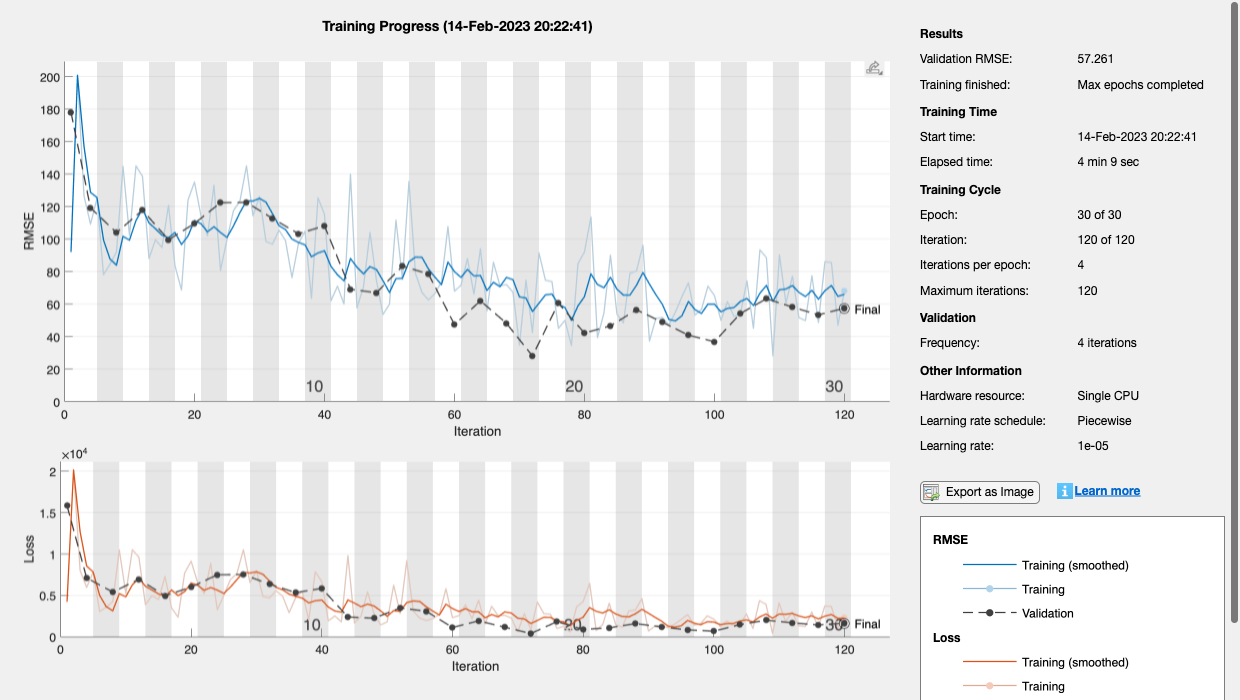

% Training with Image
net = trainNetwork(XTrain,YTrain,layers,options);

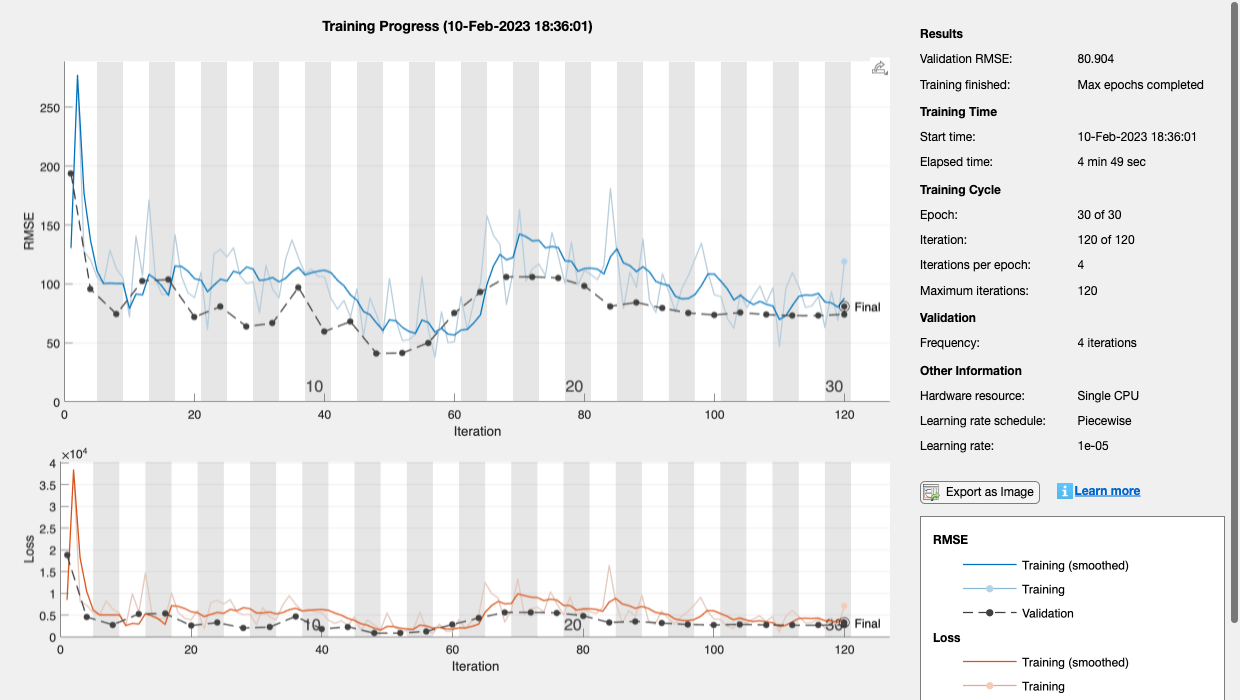

% Training with Augmented Image
net = trainNetwork(augimds,layers,options);

net.Layers

ans =   22×1 Layer array with layers:

     1   'imageinput'         Image Input           250×250×3 images with 'zerocenter' normalization
     2   'conv_1'             2-D Convolution       32 3×3×3 convolutions with stride [1  1] and padding 'same'
     3   'batchnorm_1'        Batch Normalization   Batch normalization with 32 channels
     4   'relu_1'             ReLU                  ReLU
     5   'maxpool_1'          2-D Max Pooling       2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'dropout_1'          Dropout               25% dropout
     7   'conv_2'             2-D Convolution       32 3×3×32 convolutions with stride [1  1] and padding 'same'
     8   'batchnorm_2'        Batch Normalization   Batch normalization with 32 channels
     9   'relu_2'             ReLU                  ReLU
    10   'maxpool_2'          2-D Max Pooling       2×2 max pooling with stride [2  2] and

YPredicted = predict(net,XTest);

rmse(YPredicted,YTest)

ans = single
65.5884

mae(YPredicted - YTest)

ans = single
42.4094

YPredicted - YTest

ans = 41×1 single column vector
 -119.5337
 -140.3805
 -181.3649
   14.4201
  -10.4481
  -11.4481
   52.0959
  -20.8428
  -86.5318
 -144.6185


## Retreive weights from MATCONVNET pretrained model

run matlab/vl_setupnn ;

% Load a model and upgrade it to MatConvNet current version.
tlnet = load('imagenet-matconvnet-vgg-verydeep-16.mat') ;
tlnet = vl_simplenn_tidy(tlnet) ;

% For looking at individual conv layers
% for k = 1 : length(tlnet.layers)
%   if tlnet.layers{k}.type == "conv"
%       tlnet.layers{k}
%   end
% end

% Recreating the layers and freezing conv layers
tlNNLayers = [imageInputLayer(imageSize)];

for k = 1 : length(tlnet.layers) - 2
    layer = tlnet.layers{k};
    if layer.type == "conv"
        filterSize = size(layer.weights{1},1);
        numFilters = length(layer.weights{2});

        tlNNLayers(k) = convolution2dLayer(filterSize,numFilters,'Padding','same', ...
            'WeightLearnRateFactor',0, ...
            'BiasLearnRateFactor',0);

        tlNNLayers(k).Weights = layer.weights{1};
        tlNNLayers(k).Bias = reshape(layer.weights{2}, [1 1 numFilters]);
    elseif layer.type == "relu"
        tlNNLayers(k) = reluLayer;
    elseif layer.type == "pool"
        tlNNLayers(k) = maxPooling2dLayer(2,'Stride',2);
    end
    tlNNLayers(k).Name = layer.name;
end
tlNNLayers

tlNNLayers =   1×35 Layer array with layers:

     1   'conv1_1'   2-D Convolution   64 3×3×3 convolutions with stride [1  1] and padding 'same'
     2   'relu1_1'   ReLU              ReLU
     3   'conv1_2'   2-D Convolution   64 3×3×64 convolutions with stride [1  1] and padding 'same'
     4   'relu1_2'   ReLU              ReLU
     5   'pool1'     2-D Max Pooling   2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2_1'   2-D Convolution   128 3×3×64 convolutions with stride [1  1] and padding 'same'
     7   'relu2_1'   ReLU              ReLU
     8   'conv2_2'   2-D Convolution   128 3×3×128 convolutions with stride [1  1] and padding 'same'
     9   'relu2_2'   ReLU              ReLU
    10   'pool2'     2-D Max Pooling   2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    11   'conv3_1'   2-D Convolution   256 3×3×128 convolutions with stride [1  1] and padding 'same'

tlLayers = [imageInputLayer(imageSize)
    transpose(tlNNLayers)
    flattenLayer
    fullyConnectedLayer(1024)
    batchNormalizationLayer
    reluLayer
    dropoutLayer(0.2)
    fullyConnectedLayer(256)
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer
    ]

tlLayers =   45×1 Layer array with layers:

     1   ''          Image Input           224×224×3 images with 'zerocenter' normalization
     2   'conv1_1'   2-D Convolution       64 3×3×3 convolutions with stride [1  1] and padding 'same'
     3   'relu1_1'   ReLU                  ReLU
     4   'conv1_2'   2-D Convolution       64 3×3×64 convolutions with stride [1  1] and padding 'same'
     5   'relu1_2'   ReLU                  ReLU
     6   'pool1'     2-D Max Pooling       2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'conv2_1'   2-D Convolution       128 3×3×64 convolutions with stride [1  1] and padding 'same'
     8   'relu2_1'   ReLU                  ReLU
     9   'conv2_2'   2-D Convolution       128 3×3×128 convolutions with stride [1  1] and padding 'same'
    10   'relu2_2'   ReLU                  ReLU
    11   'pool2'     2-D Max Pooling       2×2 max pooling with stride [2 

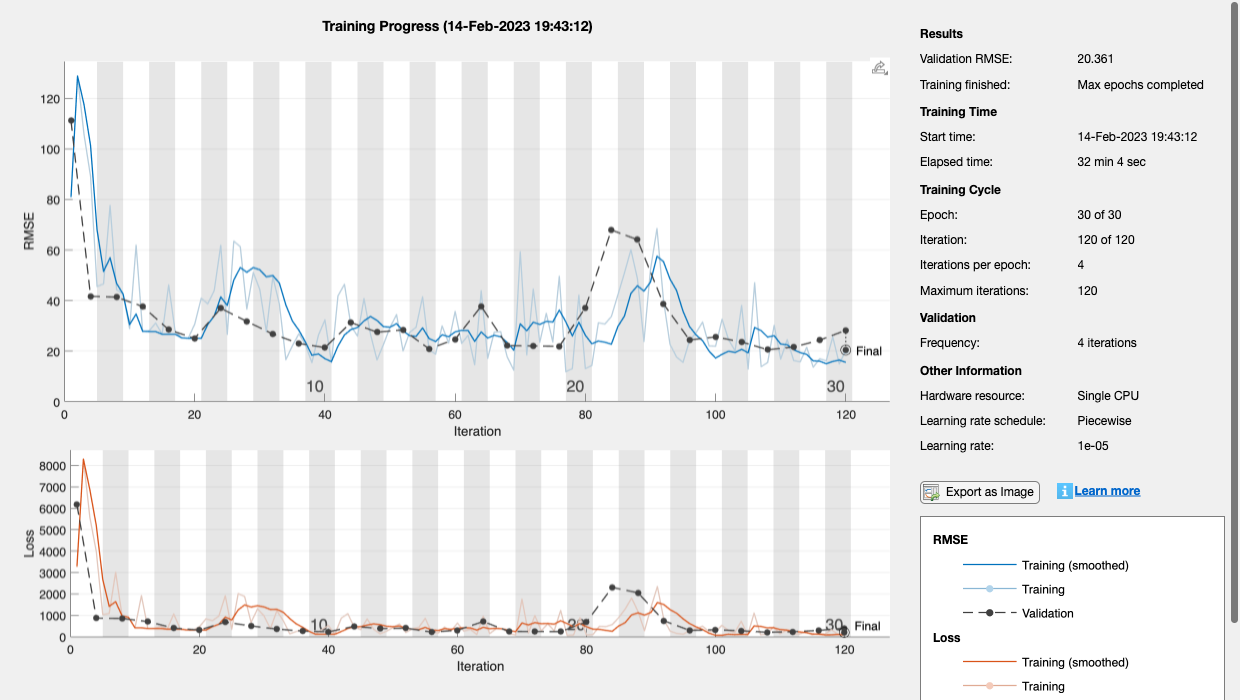

tlnet = trainNetwork(XTrain,YTrain,tlLayers,options);

YPredictedTL = predict(tlnet,XTest);

rmse(YPredictedTL, YTest)

ans = single
28.9443

mae(YPredictedTL - YTest)

ans = single
19.1978

YPredictedTL - YTest

ans = 41×1 single column vector
   39.0729
   -0.5171
   -4.5742
    4.0960
    3.8400
   21.0922
   38.8133
  -29.0878
    3.4970
   31.7956
